tic
%variables
clear
close

arrowscale=.6;
quivercolor='b';
fontsize=12;
markersize=50;
Esize=25;

fontweight='bold';


Fcolor=[0.5 0 1];
dScolor=[0 0.7 0.5];
Mcolor=[0.7 0.2 0.2];
Ecolor=[1 0 0];
K0color=[0 0 1];
CHcolor=[0 0 0];
dotcolor='k';


g=1;
interval=.2;
a=1;





[Xtemp Ytemp Ztemp]=meshgrid(sym(0:interval:1),sym(0:interval:1),(nthroot(g,a+1))*sym(0:interval:1));

X=Xtemp((Ytemp<=1-Xtemp) & (Ztemp<=(nthroot(g,a+1)*Xtemp)) & Xtemp<=1);
Y=Ytemp((Ytemp<=1-Xtemp) & (Ztemp<=(nthroot(g,a+1)*Xtemp)) & Xtemp<=1);
Z=Ztemp((Ytemp<=1-Xtemp) & (Ztemp<=(nthroot(g,a+1)*Xtemp)) & Xtemp<=1);


P=(g-1)*X-Z.^(a+1)./X.^a;
P(Z==0)=(g-1)*X(Z==0);
P(X==Z)=(g-2)*X(X==Z);

q=1/2*(3*P+X-2*Y);

U=(2*q-1).*X-3*P;
V=2*(1+q).*Y;
T=2*(1+q).*Z;

L=sqrt(U.^2+V.^2+T.^2);


Xsol=X(U==0 & V==0 & T==0 & (X==0 | Y==0 | Z==0));
Ysol=Y(U==0 & V==0 & T==0 & (X==0 | Y==0 | Z==0));
Zsol=Z(U==0 & V==0 & T==0 & (X==0 | Y==0 | Z==0));



genobj=hgtransform;

omazeroobj=hgtransform('Parent',genobj);
lambdazeroobj=hgtransform('Parent',genobj);
ooaobj=hgtransform('Parent',genobj);

transkneghpos=makehgtform('translate',[-1 0 0]);
rotkneghpos=makehgtform('zrotate',3*pi/4);
scalekneghpos=makehgtform('scale',[1 1/sqrt(2) 1]);
transbackkneghpos=makehgtform('translate',[1 1 0]);

movekneghpos=transbackkneghpos*scalekneghpos*rotkneghpos*transkneghpos;


rotkneghneg=makehgtform('xrotate',pi);
transkneghneg=makehgtform('translate',[1 0 0]);
rotkneghneg2=makehgtform("zrotate",-3*pi/4);
scalekneghneg=makehgtform('scale',[1 1/sqrt(2) 1]);
transbackkneghneg=makehgtform('translate',[-1 1 0]);

movekneghneg=transbackkneghneg*scalekneghneg*rotkneghneg2*transkneghneg*rotkneghneg;


%A=0 submanifold
omazerokneghpos=hgtransform('Parent',omazeroobj);
omazerokneghneg=hgtransform('Parent',omazeroobj);

set(omazerokneghpos,'Matrix',movekneghpos);

set(omazerokneghneg,'Matrix',movekneghneg);


XA0=X(Z==0);
YA0=Y(Z==0);
ZA0=Z(Z==0);

UA0=U(Z==0);
VA0=V(Z==0);
TA0=T(Z==0);

LA0=L(Z==0);


XsolA0=X(U==0 & V==0 & T==0 & Z==0);
YsolA0=Y(U==0 & V==0 & T==0 & Z==0);
ZsolA0=Z(U==0 & V==0 & T==0 & Z==0);


dotcolors=zeros(length(XsolA0),3);
dotcolors(XsolA0+YsolA0==1,:)=repmat(K0color,size(dotcolors(XsolA0+YsolA0==1,:),1),1);
dotcolors(XsolA0==0 & YsolA0==0,:)=Mcolor;
dotcolors(XsolA0==1 & YsolA0==0,:)=repmat(Fcolor,size(dotcolors(XsolA0==1 & YsolA0==0,:),1),1);
dotcolors(XsolA0==0 & YsolA0==1,:)=repmat(dScolor,size(dotcolors(XsolA0==0 & YsolA0==1,:),1),1);


scatter3(XsolA0,YsolA0,ZsolA0,markersize,dotcolors,'filled','Parent',omazerokneghpos);
scatter3(-XsolA0,-YsolA0,-ZsolA0,markersize,dotcolors,'filled','Parent',omazerokneghneg);

q3DkneghposA0=quiver3D([double(XA0(:)),double(YA0(:)),double(ZA0(:))],[double(UA0(:)./LA0(:)),double(VA0(:)./LA0(:)),double(TA0(:)./LA0(:))]/7,'k',.4);
q3DkneghnegA0=quiver3D([-double(XA0(:)),-double(YA0(:)),-double(ZA0(:))],[double(UA0(:)./LA0(:)),double(VA0(:)./LA0(:)),double(TA0(:)./LA0(:))]/7,'k',.4);



set(q3DkneghposA0,'Parent',omazerokneghpos);
set(q3DkneghnegA0,'Parent',omazerokneghneg);

    %Omega A=0 streamlines
    f=@(t,x)     [(3*((g-1)*x(1))+x(1)-2*x(2)-1)*x(1)-3*((g-1)*x(1));
                    2*(1+1/2*(3*((g-1)*x(1))+x(1)-2*x(2)))*x(2);
                    0];
         
    xstart=[.5 .5 .5 0];
    ystart=[0 .5 .25 .5];
    zstart=zeros(1,length(xstart));

    
    for ii=1:length(xstart)
        [ta, ya]=ode45(f,[0 20],[xstart(ii) ystart(ii) zstart(ii)]);
        plot3(ya(:,1),ya(:,2),ya(:,3),'Color','k','Parent',omazerokneghpos)
        plot3(-ya(:,1),-ya(:,2),-ya(:,3),'Color','r','Parent',omazerokneghneg)
        hold on
        
        [ta, ya]=ode45(f,[0 -20],[xstart(ii) ystart(ii) zstart(ii)]);
        plot3(ya(:,1),ya(:,2),ya(:,3),'Color','r','Parent',omazerokneghpos)
        plot3(-ya(:,1),-ya(:,2),-ya(:,3),'Color','k','Parent',omazerokneghneg);
    end
% lighting phong;
% camlight head;
hold on


%Lambda=0 submanifold
lambdazerokneghpos=hgtransform('Parent',lambdazeroobj);
lambdazerokneghneg=hgtransform('Parent',lambdazeroobj);

set(lambdazerokneghpos,'Matrix',movekneghpos);

set(lambdazerokneghneg,'Matrix',movekneghneg);


XL0=X(Y==0);
YL0=Y(Y==0);
ZL0=Z(Y==0);

UL0=U(Y==0);
VL0=V(Y==0);
TL0=T(Y==0);

LL0=L(Y==0);


XsolL0=X(U==0 & V==0 & T==0 & Y==0);
YsolL0=Y(U==0 & V==0 & T==0 & Y==0);
ZsolL0=Z(U==0 & V==0 & T==0 & Y==0);

dotcolors=zeros(length(XsolL0),3);
dotcolors(XsolL0+YsolL0==1,:)=repmat(K0color,size(dotcolors(XsolL0+YsolL0==1,:),1),1);
dotcolors(XsolL0==0 & YsolL0==0,:)=Mcolor;
dotcolors(XsolL0==0 & YsolL0==1,:)=repmat(dScolor,size(dotcolors(XsolL0==0 & YsolL0==1,:),1),1);
dotcolors(XsolL0==1 & ZsolL0==nthroot(g,a+1),:)=repmat(CHcolor,size(dotcolors(XsolL0==1 & ZsolL0==nthroot(g,a+1),:),1),1);
dotcolors(XsolL0==1 & YsolL0==0 & ZsolL0==0,:)=repmat(Fcolor,size(dotcolors(XsolL0==1 & YsolL0==0 & ZsolL0==0,:),1),1);

scatter3(XsolL0,YsolL0,ZsolL0,markersize,dotcolors,'filled','Parent',lambdazerokneghpos);
scatter3(-XsolL0,-YsolL0,-ZsolL0,markersize,dotcolors,'filled','Parent',lambdazerokneghneg);

q3DkneghposL0=quiver3D([double(XL0(:)),double(YL0(:)),double(ZL0(:))],[double(UL0(:)./LL0(:)),double(VL0(:)./LL0(:)),double(TL0(:)./LL0(:))]/7,'k',.4);
q3DkneghnegL0=quiver3D([-double(XL0(:)),-double(YL0(:)),-double(ZL0(:))],[double(UL0(:)./LL0(:)),double(VL0(:)./LL0(:)),double(TL0(:)./LL0(:))]/7,'k',.4);

set(q3DkneghposL0,'Parent',lambdazerokneghpos);
set(q3DkneghnegL0,'Parent',lambdazerokneghneg);

%Omega Lambda=0 streamlines
    f=@(t,x)     [((3*((g-1)*x(1)-x(3)^(a+1)/x(1)^a)+x(1))-1)*x(1)-3*((g-1)*x(1)-x(3)^(a+1)/x(1)^a);
                    0;
                    2*(1+1/2*(3*((g-1)*x(1)-x(3)^(a+1)/x(1)^a)+x(1)))*x(3)];
         
    xstart=[1 .7 .5 .5];
    ystart=[0 0 0 0];
    zstart=[nthroot(g,a+1)/2 nthroot(g,a+1)/4 0 nthroot(g,a+1)*.5];

    
    for ii=1:length(xstart)
        [ta, ya]=ode45(f,[0 20],[xstart(ii) ystart(ii) zstart(ii)]);
        plot3(ya(:,1),ya(:,2),ya(:,3),'Color','k','Parent',lambdazerokneghpos)
        plot3(-ya(:,1),-ya(:,2),-ya(:,3),'Color','r','Parent',lambdazerokneghneg)
        hold on
        
        [ta, ya]=ode45(f,[0 -20],[xstart(ii) ystart(ii) zstart(ii)]);
        plot3(ya(:,1),ya(:,2),ya(:,3),'Color','r','Parent',lambdazerokneghpos)
        plot3(-ya(:,1),-ya(:,2),-ya(:,3),'Color','k','Parent',lambdazerokneghneg);
    end


% lighting phong;
% camlight head;
hold on


%OmegaA=nthroot(g,a+1)*Omega submanifold
ooakneghpos=hgtransform('Parent',ooaobj);
ooakneghneg=hgtransform('Parent',ooaobj);

set(ooakneghpos,'Matrix',movekneghpos);

set(ooakneghneg,'Matrix',movekneghneg);

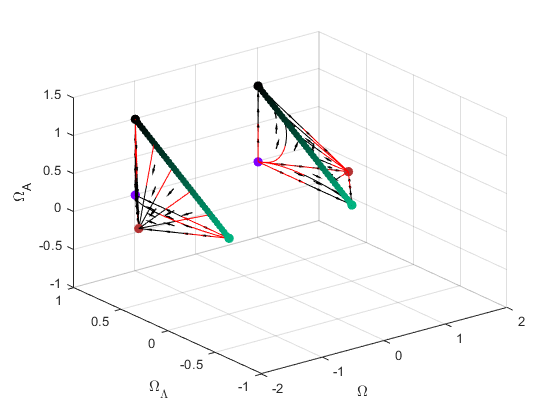


XAGO=X(Z==nthroot(g,a+1)*X);
YAGO=Y(Z==nthroot(g,a+1)*X);
ZAGO=Z(Z==nthroot(g,a+1)*X);

UAGO=U(Z==nthroot(g,a+1)*X);
VAGO=V(Z==nthroot(g,a+1)*X);
TAGO=T(Z==nthroot(g,a+1)*X);

LAGO=L(Z==nthroot(g,a+1)*X);


XsolAGO=X(U==0 & V==0 & T==0 & Z==nthroot(g,a+1)*X & (X==0 | Y==0 | Z==0));
YsolAGO=Y(U==0 & V==0 & T==0 & Z==nthroot(g,a+1)*X & (X==0 | Y==0 | Z==0));
ZsolAGO=Z(U==0 & V==0 & T==0 & Z==nthroot(g,a+1)*X & (X==0 | Y==0 | Z==0));


dotcolors=zeros(length(XsolAGO),3);
dotcolors(XsolAGO+YsolAGO==1,:)=repmat(K0color,size(dotcolors(XsolAGO+YsolAGO==1,:),1),1);
dotcolors(XsolAGO==0 & YsolAGO==0,:)=Mcolor;
dotcolors(XsolAGO==1 & YsolAGO==0,:)=Fcolor;
dotcolors(XsolAGO==0 & YsolAGO==1,:)=dScolor;
dotcolors(XsolAGO==1 & ZsolAGO==nthroot(g,a+1),:)=repmat(CHcolor,size(dotcolors(XsolAGO==1 & ZsolAGO==nthroot(g,a+1),:),1),1);


scatter3(XsolAGO,YsolAGO,ZsolAGO,markersize,dotcolors,'filled','Parent',ooakneghpos);
scatter3(-XsolAGO,-YsolAGO,-ZsolAGO,markersize,dotcolors,'filled','Parent',ooakneghneg);


q3DkneghposAGO=quiver3D([double(XAGO(:)),double(YAGO(:)),double(ZAGO(:))],[double(UAGO(:)./LAGO(:)),double(VAGO(:)./LAGO(:)),double(TAGO(:)./LAGO(:))]/7,'k',.4);
q3DkneghnegAGO=quiver3D([-double(XAGO(:)),-double(YAGO(:)),-double(ZAGO(:))],[double(UAGO(:)./LAGO(:)),double(VAGO(:)./LAGO(:)),double(TAGO(:)./LAGO(:))]/7,'k',.4);

set(q3DkneghposAGO,'Parent',ooakneghpos);
set(q3DkneghnegAGO,'Parent',ooakneghneg);
% 
% lighting phong;
% camlight head;

% set(q3Dkneghpos,'Parent',kneghpos);

%Omega A = nthroot(g,a+1)*Omega streamlines


    xstart=0:.1:.5;
    ystart=.5-xstart;
    zstart=nthroot(g,a+1)*xstart;

    f=@(t,x)     [(2*(-x(1)-x(2))-1)*x(1)+3*x(1);
                    2*(1+(-x(1)-x(2)))*x(2);
                    2*(1+(-x(1)-x(2)))*x(3)];
    
    for ii=1:length(xstart)
        [ta, ya]=ode45(f,[0 20],[xstart(ii) ystart(ii) zstart(ii)]);
        plot3(ya(:,1),ya(:,2),ya(:,3),'Color','k','Parent',ooakneghpos)
        plot3(-ya(:,1),-ya(:,2),-ya(:,3),'Color','r','Parent',ooakneghneg)
        hold on
        
        [ta, ya]=ode45(f,[0 -20],[xstart(ii) ystart(ii) zstart(ii)]);
        plot3(ya(:,1),ya(:,2),ya(:,3),'Color','r','Parent',ooakneghpos)
        plot3(-ya(:,1),-ya(:,2),-ya(:,3),'Color','k','Parent',ooakneghneg);
    end

    
    cdx=linspace(0,1,40);
    cdy=1-cdx;
    cdz=nthroot(g,a+1)*cdx;
    
    cdcolors=(1-cdx')*dScolor;
    
    % plot3(cdx,[1 0],[0 nthroot(g,a+1)],'LineWidth',5,'Color',K0color,'Parent',kneghpos);
    % plot3(-[0 1],-[1 0],-[0 nthroot(g,a+1)],'LineWidth',5,'Color',K0color,'Parent',kneghneg);
    
    scatter3(cdx,cdy,cdz,markersize/2,cdcolors,'filled','Parent',ooakneghpos);
    scatter3(-cdx,-cdy,-cdz,markersize/2,cdcolors,'filled','Parent',ooakneghneg);

hold on



xlabel('\Omega')
ylabel('\Omega_\Lambda')
zlabel('\Omega_A')

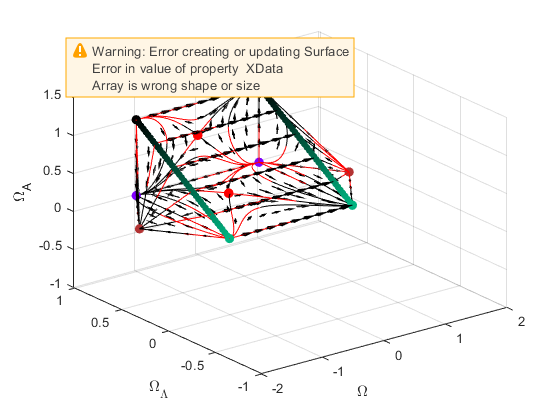

[Xtemp Ytemp Ztemp]=meshgrid(sym(-1:interval:1),sym(0:interval:1),(nthroot(g,a+1))*sym(0:interval:1));

X=Xtemp(Ztemp<=(nthroot(g,a+1)*Ytemp) & Ytemp<=1);
Y=Ytemp(Ztemp<=(nthroot(g,a+1)*Ytemp) & Ytemp<=1);
Z=Ztemp(Ztemp<=(nthroot(g,a+1)*Ytemp) & Ytemp<=1);

P=(g-1)*Y-Z.^(a+1)./Y.^a;
P(Z==0)=(g-1)*Y(Z==0);
P(Y==Z)=(g-2)*Y(Y==Z);


U=(X.^2-1).*(3/2*(Y+P)-1);
V=3*X.*(Y+P).*(Y-1);
T=3*X.*(Y+P).*Z;



L=sqrt(U.^2+V.^2+T.^2);
L=double(L);
L(L==0)=1;

ucolor=double(U./L);
vcolor=double(V./L);
tcolor=double(T./L);

% arrowcolors=([ucolor vcolor tcolor]+1)/2;

arrowcolors=abs([ucolor vcolor tcolor]);

arrowcolors=double(subs(arrowcolors,NaN,1));




%A=0 submanifold
omazerokpos=hgtransform('Parent',omazeroobj);

syms x real
    
    assume(x>0);
    eqn=(g*x^(a+1)-2/3*x^a)^(1/(a+1));
    solom=double(solve(eqn,x));
    if solom<=1
        plot3(0,solom,0,'.','MarkerSize',Esize,'Color',Ecolor,'Parent',omazerokpos);
    end
    hold on
    
    
    f=@(t,x) [(x(1)^2-1).*(3/2*(x(2)+(g-1)*x(2)-x(3)^(a+1)/x(2)^a)-1);
                3*x(1)*((g-1)*x(2)-x(3)^(a+1)/x(2)^a+x(2))*(x(2)-1);
                3*x(1)*x(3)*(x(2)+(g-1)*x(2)-x(3)^(a+1)/x(2)^a)];
    
    

    if solom<=1
    
       [ta ya]=ode45(f,[0 20],[0 solom-.02 0]);
        plot3(ya(1:29,1),ya(1:29,2),ya(1:29,3),'Color','r','Parent',omazerokpos);
        plot3(ya(29:end,1),ya(29:end,2),ya(29:end,3),'Color','k','Parent',omazerokpos);

        
        [ta ya]=ode45(f,[0 -20],[0 solom-.02 0]);
        plot3(ya(1:27,1),ya(1:27,2),ya(1:27,3),'Color','k','Parent',omazerokpos)
        plot3(ya(27:end,1),ya(27:end,2),ya(27:end,3),'Color','r','Parent',omazerokpos)

        
        [ta ya]=ode45(f,[0 20],[0 solom+.02 0]);
    
        plot3(ya(1:26,1),ya(1:26,2),ya(1:26,3),'Color','r','Parent',omazerokpos);
        plot3(ya(26:end,1),ya(26:end,2),ya(26:end,3),'Color','k','Parent',omazerokpos);

        
        [ta ya]=ode45(f,[0 -20],[0 solom+.02 0]);
        plot3(ya(1:27,1),ya(1:27,2),ya(1:27,3),'Color','k','Parent',omazerokpos)
        plot3(ya(27:end,1),ya(27:end,2),ya(27:end,3),'Color','r','Parent',omazerokpos)
    
    end
    

    if g>2/3
        xstart=[0 -.7 .7 0 0];
        ystart=[1 solom solom  solom/2 (1+solom)/2];
        zstart=[0 0 0 0 0];
    else
        xstart=[0 0 0];
        ystart=[1 .4 .8];
        zstart=[0 0 0];
    end
          
           
           
    for ii=1:length(xstart)
       [ta ya]=ode45(f,[0 20],[xstart(ii), ystart(ii), zstart(ii)]);
       plot3(ya(:,1),ya(:,2),ya(:,3),'Color','k','Parent',omazerokpos);
       hold on
       
           
       [ta ya]=ode45(f,[0 -20],[xstart(ii), ystart(ii), zstart(ii)]);
       plot3(ya(:,1),ya(:,2),ya(:,3),'Color','r','Parent',omazerokpos);
    end    
    
    
    
    
XA0=X(Z==0);
YA0=Y(Z==0);
ZA0=Z(Z==0);

UA0=U(Z==0);
VA0=V(Z==0);
TA0=T(Z==0);

LA0=L(Z==0);

q3DkposA0=quiver3D([double(XA0(:)),double(YA0(:)),double(ZA0(:))],[double(UA0(:)./LA0(:)),double(VA0(:)./LA0(:)),double(TA0(:)./LA0(:))]/7,'k',.4);
set(q3DkposA0,'Parent',omazerokpos);


% 
% lighting phong;
% camlight head;
hold on






%Lambda=0 submanifold
lambdazerokpos=hgtransform('Parent',lambdazeroobj);

f=@(t,x)   [(x(1)^2-1)*(3/2*(1+(g-1)-x(3)^(a+1))-1);
            0;
            3*x(1)*(1+(g-1)-x(3)^(a+1))*x(3)];
            
    om=1;
    if (g*om^(a+1)-2/3*om^a)>=0
        oma=(g*om^(a+1)-2/3*om^a)^(1/(1+a));
        plot3(0,om,oma,'.','MarkerSize',Esize,'Color',Ecolor,'Parent',lambdazerokpos);
        
        [ta ya]=ode45(f,[0 20],[0 1 oma-0.02]);
    
        plot3(ya(1:26,1),ya(1:26,2),ya(1:26,3),'Color','r','Parent',lambdazerokpos);
        plot3(ya(26:end,1),ya(26:end,2),ya(26:end,3),'Color','k','Parent',lambdazerokpos);

        
        [ta ya]=ode45(f,[0 -20],[0 1 oma-0.02]);
        plot3(ya(1:27,1),ya(1:27,2),ya(1:27,3),'Color','k','Parent',lambdazerokpos)
        plot3(ya(27:end,1),ya(27:end,2),ya(27:end,3),'Color','r','Parent',lambdazerokpos)

        
         [ta ya]=ode45(f,[0 20],[0 1 oma+0.02]);
    
        plot3(ya(1:26,1),ya(1:26,2),ya(1:26,3),'Color','r','Parent',lambdazerokpos);
        plot3(ya(26:end,1),ya(26:end,2),ya(26:end,3),'Color','k','Parent',lambdazerokpos);

        
        [ta ya]=ode45(f,[0 -20],[0 1 oma+0.02]);
        plot3(ya(1:27,1),ya(1:27,2),ya(1:27,3),'Color','k','Parent',lambdazerokpos)
        plot3(ya(27:end,1),ya(27:end,2),ya(27:end,3),'Color','r','Parent',lambdazerokpos)
    end 
    
    
    if g>2/3
        xstart=[0 -.5 .5 0 0];
        ystart=[1 1 1 1 1];
        zstart=[0 oma oma oma/2 (1+oma)/2];
    else
        xstart=[0 0 0];
        ystart=[1 1 1];
        zstart=[0 (nthroot(g,a+1)-.2)/2 (nthroot(g,a+1)-.2)];
    end
          
           
           
    for ii=1:length(xstart)
       [ta ya]=ode45(f,[0 20],[xstart(ii), ystart(ii), zstart(ii)]);
       plot3(ya(:,1),ya(:,2),ya(:,3),'Color','k','Parent',lambdazerokpos);
       hold on
       
           
       [ta ya]=ode45(f,[0 -20],[xstart(ii), ystart(ii), zstart(ii)]);
       plot3(ya(:,1),ya(:,2),ya(:,3),'Color','r','Parent',lambdazerokpos);
    end

XL0=X(Y==1);
YL0=Y(Y==1);
ZL0=Z(Y==1);

UL0=U(Y==1);
VL0=V(Y==1);
TL0=T(Y==1);

LL0=L(Y==1);
arrowcolorsL0=arrowcolors(Y==1,:);



q3DkposL0=quiver3D([double(XL0(:)),double(YL0(:)),double(ZL0(:))],[double(UL0(:)./LL0(:)),double(VL0(:)./LL0(:)),double(TL0(:)./LL0(:))]/7,'k',.4);

set(q3DkposL0,'Parent',lambdazerokpos);


lighting phong;
camlight head;
hold on







%OmegaA=nthroot(g,a+1)*Omega submanifold
ooakpos=hgtransform('Parent',ooaobj);

XAGO=X(Z==nthroot(g,a+1)*Y);
YAGO=Y(Z==nthroot(g,a+1)*Y);
ZAGO=Z(Z==nthroot(g,a+1)*Y);

UAGO=U(Z==nthroot(g,a+1)*Y);
VAGO=V(Z==nthroot(g,a+1)*Y);
TAGO=T(Z==nthroot(g,a+1)*Y);

LAGO=L(Z==nthroot(g,a+1)*Y);
arrowcolorsAGO=arrowcolors(Z==nthroot(g,a+1)*Y,:);



q3DkposAGO=quiver3D([double(XAGO(:)),double(YAGO(:)),double(ZAGO(:))],[double(UAGO(:)./LAGO(:)),double(VAGO(:)./LAGO(:)),double(TAGO(:)./LAGO(:))]/5,'k',.2);

set(q3DkposAGO,'Parent',ooakpos);
%Omega A = nthroot(g,a+1)*Omega streamlines
    xstart=[0 0 0 0 0 0];
    ystart=[0 .2 .4 .6 .8 1];
    zstart=nthroot(g,a+1)*ystart; 
    
    f=@(t,x) [-(x(1)^2-1);
                0;
                0];
    
    for ii=1:length(xstart)
        [ta, ya]=ode45(f,[0 20],[xstart(ii) ystart(ii) zstart(ii)]);
        plot3(ya(:,1),ya(:,2),ya(:,3),'Color','k','Parent',ooakpos)
        hold on
        
        [ta, ya]=ode45(f,[0 -20],[xstart(ii) ystart(ii) zstart(ii)]);
        plot3(ya(:,1),ya(:,2),ya(:,3),'Color','r','Parent',ooakpos)
    end

% scalegeneralobj=makehgtform('scale',double([1 1 1/(nthroot(g,a+1))]));
% set(genobj,'Matrix',scalegeneralobj);



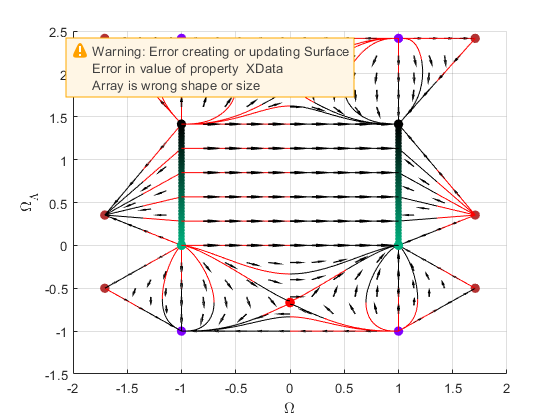





rotateomazero=makehgtform('xrotate',pi);
set(omazeroobj,'Matrix',rotateomazero);


rotateago=makehgtform('xrotate',-double(atan(nthroot(g,a+1))));
set(ooaobj,'Matrix',rotateago);

translambdazero=makehgtform('translate',[0 -1 0]);
rotlambdazero=makehgtform('xrotate',pi/2);
transbacklambdazero=makehgtform('translate',[0 double(sqrt(nthroot(g,a+1)^2+1)+nthroot(g,a+1)) 0]);

movelambdazero=transbacklambdazero*rotlambdazero*translambdazero;

set(lambdazeroobj,'Matrix',movelambdazero);

view(0,90)

toc

Elapsed time is 15.027238 seconds.


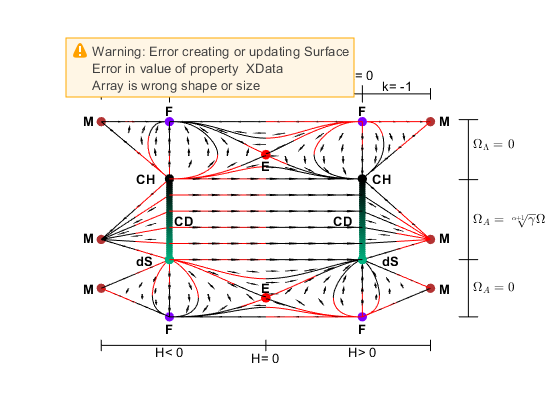

fontweight='bold';
fontsize=10;

if g>2/3
    text([-1.05 -1.05 .95 .95],[-1.2 2.61 -1.2 2.61],[0 0 0 0],'F','FontWeight',fontweight,'FontSize',fontsize);
    text([-1.9 -1.9 -1.9 1.8 1.8 1.8],[-0.5 0.4 2.45 -0.5 0.4 2.45],[0 0 0 0 0 0],'M','FontWeight',fontweight,'FontSize',fontsize);
    text([-1.35 1.2],[0 0],[0 0],'dS','FontWeight',fontweight,'FontSize',fontsize)
    text([-1.35 1.1],[1.43 1.43],[0 0],'CH','FontWeight',fontweight,'FontSize',fontsize)
    text([-.95 .7],[.7 .7],[0 0],'CD','FontWeight',fontweight,'FontSize',fontsize)
    text([-.05 -.05],[-.48 1.65],[0 0],'E','FontWeight',fontweight,'FontSize',fontsize)
    plot3([-(1+sqrt(2)/2) 1+sqrt(2)/2],[2.9 2.9],[0 0],'Color','k');
    plot3([-(1+sqrt(2)/2) -1 1 (1+sqrt(2)/2); -(1+sqrt(2)/2) -1 1 (1+sqrt(2)/2)],[2.8 2.75 2.75 2.8;3 3.05 3.05 3],[0 0 0 0;0 0 0 0],'Color','k');
    plot3([-(1+sqrt(2)/2) (1+sqrt(2)/2)],[-1.5 -1.5],[0 0],'Color','k');
    plot3([0 -(1+sqrt(2)/2) (1+sqrt(2)/2); 0 -(1+sqrt(2)/2) (1+sqrt(2)/2)],[-1.6 -1.6 -1.6; -1.4 -1.4 -1.4],[0 0 0;0 0 0],'Color','k');
    plot3([2.1 2.1],[-1 2.45],[0 0],'Color','k');
    plot3([2 2 2 2;2.2 2.2 2.2 2.2],[-1 0 1.4 2.45; -1 0 1.4 2.45],[0 0 0 0;0 0 0 0],'Color','k');
    text([-.15 -1.15 .85],[-1.7 -1.6 -1.6],[0 0 0],{'H= 0','H< 0','H> 0'});
    text([-1.5 -1.15 -.15 .85 1.2],[3.05 3.25 3.05 3.25 3.05],[0 0 0 0 0],{'k= -1','k= 0','k= +1','k= 0','k= -1'});
    text([2.15 2.15 2.15],[-0.5 0.7 2],[0 0 0],{'$\Omega_A=0$','$\Omega_A=\sqrt[\alpha + 1]{\gamma}\Omega$','$\Omega_\Lambda=0$'},'interpreter','latex')
elseif g<2/3
    text([-1.05 -1.05 .95 .95],[-1.2 2.1 -1.2 2.1],[0 0 0 0],'F','FontWeight',fontweight,'FontSize',fontsize);
    text([-1.9 -1.9 -1.9 1.8 1.8 1.8],[-0.5 0.4 2 -0.5 0.4 2],[0 0 0 0 0 0],'M','FontWeight',fontweight,'FontSize',fontsize);
    text([-1.35 1.2],[0 0],[0 0],'dS','FontWeight',fontweight,'FontSize',fontsize)
    text([-1.35 1.1],[sqrt(5)/2+.1 sqrt(5)/2+.1],[0 0],'CH','FontWeight',fontweight,'FontSize',fontsize)
    text([-.95 .7],[.6 .6],[0 0],'CD','FontWeight',fontweight,'FontSize',fontsize)
    plot3([-(1+sqrt(2)/2) 1+sqrt(2)/2],[sqrt(5)/2+1.2 sqrt(5)/2+1.2],[0 0],'Color','k');
    plot3([-(1+sqrt(2)/2) -1 1 (1+sqrt(2)/2); -(1+sqrt(2)/2) -1 1 (1+sqrt(2)/2)],[sqrt(5)/2+1.1 sqrt(5)/2+1.05 sqrt(5)/2+1.05 sqrt(5)/2+1.1;sqrt(5)/2+1.3 sqrt(5)/2+1.35 sqrt(5)/2+1.35 sqrt(5)/2+1.3],[0 0 0 0;0 0 0 0],'Color','k');
    plot3([-(1+sqrt(2)/2) (1+sqrt(2)/2)],[-1.5 -1.5],[0 0],'Color','k');
    plot3([0 -(1+sqrt(2)/2) (1+sqrt(2)/2); 0 -(1+sqrt(2)/2) (1+sqrt(2)/2)],[-1.6 -1.6 -1.6; -1.4 -1.4 -1.4],[0 0 0;0 0 0],'Color','k');
    plot3([2.1 2.1],[-1 1.9],[0 0],'Color','k');
    plot3([2 2 2 2;2.2 2.2 2.2 2.2],[-1 0 sqrt(5)/2+.1 1.93; -1 0 sqrt(5)/2+.1 1.93],[0 0 0 0;0 0 0 0],'Color','k');
    text([-.15 -1.15 .85],[-1.7 -1.6 -1.6],[0 0 0],{'H= 0','H< 0','H> 0'});
    text([-1.5 -1.15 -.15 .85 1.2],[sqrt(5)/2+1.35 sqrt(5)/2+1.55 sqrt(5)/2+1.35 sqrt(5)/2+1.55 sqrt(5)/2+1.35],[0 0 0 0 0],{'k= -1','k= 0','k= +1','k= 0','k= -1'});
    text([2.15 2.15 2.15],[-0.5 0.7 1.6],[0 0 0],{'$\Omega_A=0$','$\Omega_A=\sqrt[\alpha + 1]{\gamma}\Omega$','$\Omega_\Lambda=0$'},'interpreter','latex')
end



grid off
axis off
view(0,90)
%     h=gcf;
%     set(h,'PaperOrientation','landscape');
%     print('3dsubs','-djpeg', '-r600');

hold on

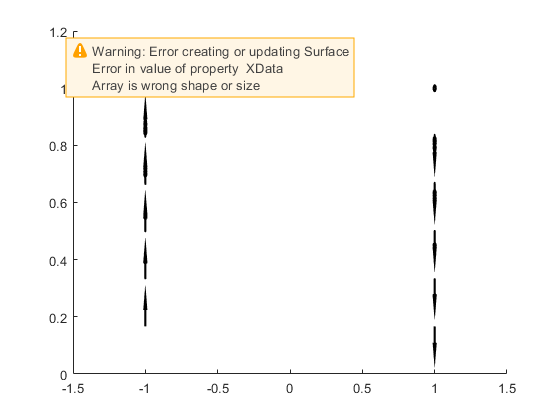

hold off
close

interval=.1;

kzerohpos=hgtransform;
kzerohneg=hgtransform;

ymesh=sym(linspace(0,1,7));

[Xtemp Ytemp Ztemp]=meshgrid(1,ymesh,(nthroot(g,a+1))*ymesh);

X=Xtemp(Ztemp<=(nthroot(g,a+1)*Ytemp) & Ytemp<=1);
Y=Ytemp(Ztemp<=(nthroot(g,a+1)*Ytemp) & Ytemp<=1);
Z=Ztemp(Ztemp<=(nthroot(g,a+1)*Ytemp) & Ytemp<=1);

P=(g-1)*Y-Z.^(a+1)./Y.^a;
P(Z==0)=(g-1)*Y(Z==0);
P(Y==Z)=(g-2)*Y(Y==Z);


U=(X.^2-1).*(3/2*(Y+P)-1);
V=3*X.*(Y+P).*(Y-1);
T=3*X.*(Y+P).*Z;



L=sqrt(U.^2+V.^2+T.^2);
L=double(L);
L(L==0)=1;

qkzerohpos=quiver3D([double(X(:)),double(Y(:)),double(Z(:))],[double(U(:)),double(V(:)),double(T(:))]./(7*L(:)),'k',.4);
qkzerohneg=quiver3D([-double(X(:)),double(Y(:)),double(Z(:))],-[double(U(:)),double(V(:)),double(T(:))]./(7*L(:)),'k',.4);

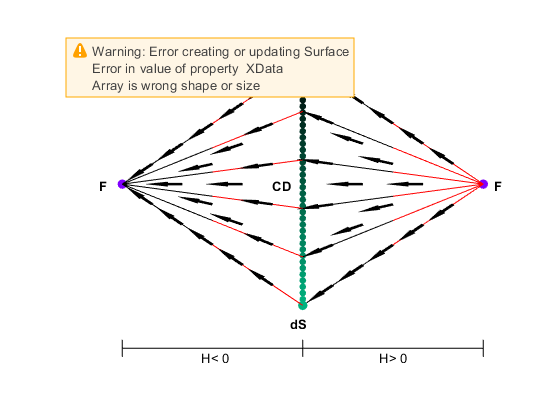



set(qkzerohpos,'Parent',kzerohpos);
set(qkzerohneg,'Parent',kzerohneg);

Xsol=X(U==0 & V==0 & T==0 & (Y==0 | Y==1));
Ysol=Y(U==0 & V==0 & T==0 & (Y==0 | Y==1));
Zsol=Z(U==0 & V==0 & T==0 & (Y==0 | Y==1));

dotcolors=zeros(length(Xsol),3);
dotcolors(Ysol==0 & Zsol==0,:)=dScolor;
dotcolors(Ysol==1 & Zsol==0,:)=Fcolor;
dotcolors(Ysol==1 & Zsol==1,:)=CHcolor;

scatter3(Xsol,Ysol,Zsol,markersize,dotcolors,'filled','Parent',kzerohpos);
scatter3(-Xsol,Ysol,Zsol,markersize,dotcolors,'filled','Parent',kzerohneg);
cdy=linspace(0,1,40);
cdx=ones(1,length(cdy));
cdz=nthroot(g,a+1)*cdy;

cdcolors=(1-cdy')*dScolor;

% plot3(cdx,[1 0],[0 nthroot(g,a+1)],'LineWidth',5,'Color',K0color,'Parent',kneghpos);
% plot3(-[0 1],-[1 0],-[0 nthroot(g,a+1)],'LineWidth',5,'Color',K0color,'Parent',kneghneg);

scatter3(cdx,cdy,cdz,markersize/2,cdcolors,'filled','Parent',kzerohpos);
% scatter3(-cdx,-cdy,-cdz,markersize/2,cdcolors,'filled','Parent',kneghneg);



f=@(t,x) [0;
        3*x(1)*(x(2)+(g-1)*x(2)-x(3)^(a+1)/x(2)^a)*(x(2)-1);
        3*x(1)*(x(2)+(g-1)*x(2)-x(3)^(a+1)/x(2)^a)*(x(3))];
    
ystart=.5:.1:1;
zstart=(ystart-.5)*nthroot(g,a+1);
xstart=ones(1,length(ystart));

    for ii=1:length(xstart)
        [ta, ya]=ode45(f,[0 20],[xstart(ii) ystart(ii) zstart(ii)]);
        plot3(ya(:,1),ya(:,2),ya(:,3),'Color','k','Parent',kzerohpos)
        hold on
        plot3(-ya(:,1),ya(:,2),ya(:,3),'Color','r','Parent',kzerohneg)
        
        
        [ta, ya]=ode45(f,[0 -20],[xstart(ii) ystart(ii) zstart(ii)]);
        plot3(ya(:,1),ya(:,2),ya(:,3),'Color','r','Parent',kzerohpos);
        plot3(-ya(:,1),ya(:,2),ya(:,3),'Color','k','Parent',kzerohneg)
    end






transkzerohpos=makehgtform('translate',[-1 -1 0]);
rotkzerohpos=makehgtform('zrotate',-pi/2);
transbackkzerohpos=makehgtform('translate',[1 0 0]);
rot2kzerohpos=makehgtform('yrotate',-double(atan(nthroot(g,a+1))));

movekzerohpos=rot2kzerohpos*transbackkzerohpos*rotkzerohpos*transkzerohpos;

set(kzerohpos,'Matrix',movekzerohpos);
transkzerohneg=makehgtform('translate',[1 0 0]);
rotkzerohneg=makehgtform('zrotate',pi/2);
rot2kzerohneg=makehgtform('yrotate',double(atan(nthroot(g,a+1))));

movekzerohneg=rot2kzerohneg*rotkzerohneg*transkzerohneg;

set(kzerohneg,'Matrix',movekzerohneg);
view(0,0)
text([-.8 .75],[0 0],[.7 .7],'F','FontWeight',fontweight,'FontSize',fontsize);
    text(-.05,0,-.1,'dS','FontWeight',fontweight,'FontSize',fontsize)
    text(-.05,0,1.5,'CH','FontWeight',fontweight,'FontSize',fontsize)
    text(-.12,0,.7,'CD','FontWeight',fontweight,'FontSize',fontsize)
    
    
    
     
    plot3([-sqrt(2)/2 -sqrt(2)/2 0 sqrt(2)/2; sqrt(2)/2 -sqrt(2)/2 0 sqrt(2)/2] ...
        ,[0 0 0 0; 0 0 0 0],[-.25 -.3 -.3 -.3; -.25 -.2 -.2 -.2],'Color','k')
    text([-.4 .3],[0 0],[-.3 -.3],{'H< 0','H> 0'})
    axis([-.9 .8  -1 1 -.4 1.6])
    axis off


% toc